a = py.worktester.matlabfun();

fluxMean_log = double(a{1});
fluxStd_log  = double(a{2});
paramBins_b  = double(a{3});
energies     = double(a{4});

paramBins = paramBins_b(1:end-1) + diff(paramBins_b)/2;
paramBins_M = repmat(paramBins, 20, 1);
energies_M = repmat(energies', 1, 30);

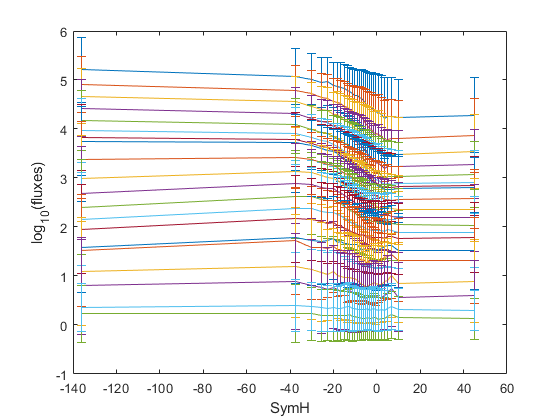

errorbar(paramBins_M', fluxMean_log', fluxStd_log');
xlabel('SymH')
ylabel('log_{10}(fluxes)')

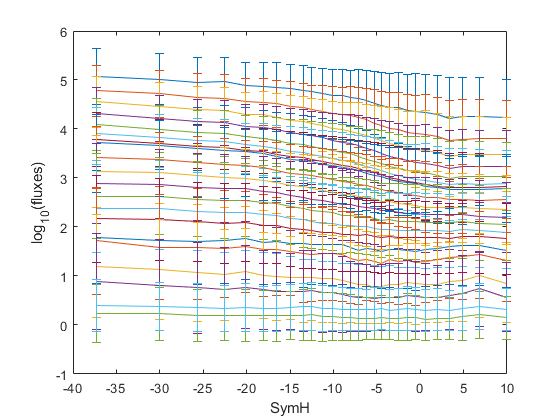

errorbar(paramBins_M(:,2:end-1)', fluxMean_log(:,2:end-1)', fluxStd_log(:,2:end-1)')
xlabel('SymH')
ylabel('log_{10}(fluxes)')

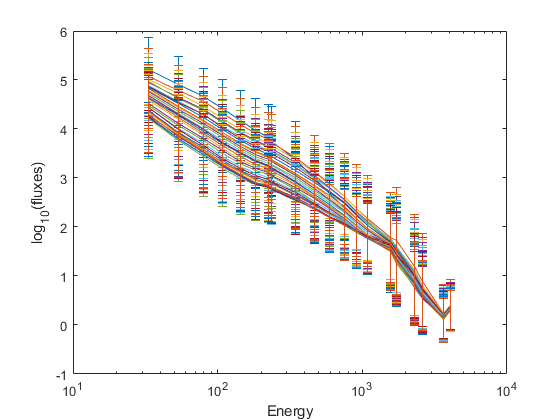

errorbar(energies_M, fluxMean_log, fluxStd_log)
set(gca,'XScale','log')
xlabel('Energy')
ylabel('log_{10}(fluxes)')

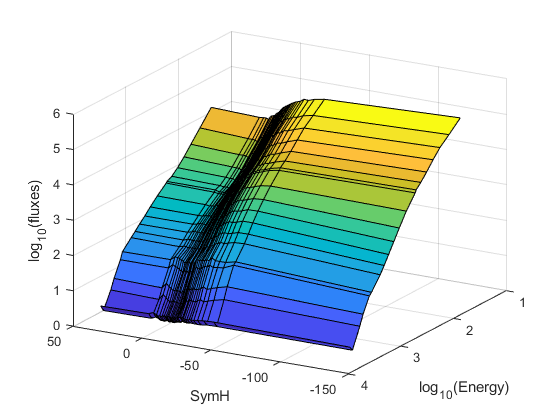

energies_log = log10(energies);
energies_log_M = log10(energies_M);
surf(paramBins_M, energies_log_M, fluxMean_log)
xlabel('SymH')
ylabel('log_{10}(Energy)')
zlabel('log_{10}(fluxes)')

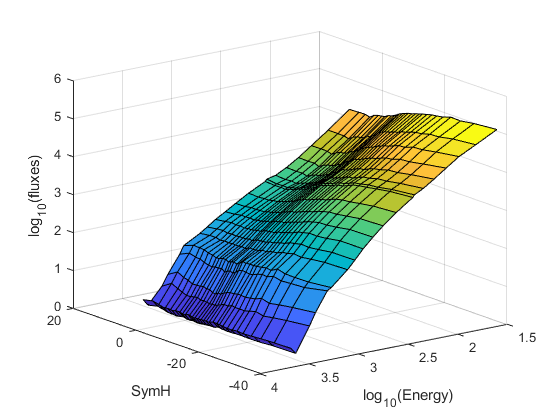

paramBins_M0 = paramBins_M(:,2:end-1);
energies_log_M0 = energies_log_M(:,2:end-1);
fluxMean_log0 = fluxMean_log(:,2:end-1);
fluxStd_log0 = fluxStd_log(:,2:end-1);

surf(paramBins_M0, energies_log_M0, fluxMean_log0)
xlabel('SymH')
ylabel('log_{10}(Energy)')
zlabel('log_{10}(fluxes)')

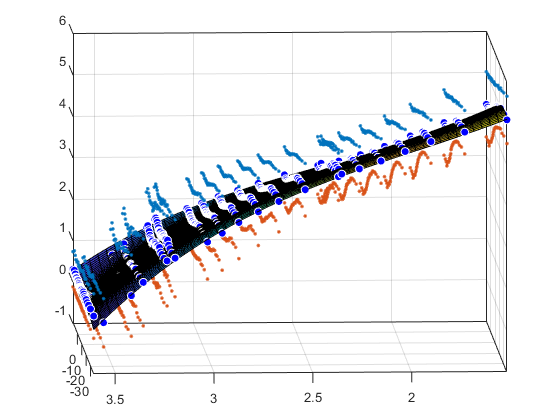

paramBins_L0 = reshape(paramBins_M0, numel(paramBins_M0), 1);
energies_log_L0 = reshape(energies_log_M0, numel(energies_log_M0), 1);
fluxMean_logL0 = reshape(fluxMean_log0, numel(fluxMean_log0), 1);
fluxStd_logL0 = reshape(fluxStd_log0, numel(fluxStd_log0), 1);

figure
clf
p = fit([paramBins_L0, energies_log_L0], fluxMean_logL0, 'poly33');
plot(p, [paramBins_L0, energies_log_L0], fluxMean_logL0)
hold on;

plot3(paramBins_L0, energies_log_L0, fluxMean_logL0+fluxStd_logL0, '.')
plot3(paramBins_L0, energies_log_L0, fluxMean_logL0-fluxStd_logL0, '.')